# Hands-On: C2D with Sampler & Hold - First Experiment

## First Scenario: Discretising  an LTI System with only Real Eigenvalues

Let's consider the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												0 & 1\\0 & -1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


What happens, if you choose a few different sampling periods $\Delta_1\,,\; \Delta_2\,, \ldots \Delta_{10}$ such that

 
$$\Delta_i \in \left[ \frac{1}{1000} \,,\; 10 \right] \quad \forall i = 1\,,\;2\,, \ldots 10$$


and then compute the discrete-time description of the considered LTI system?

Write a piece of code, allowing:

-  To select a set of sample periods, as specified above;

-  To compute, for each selected sampling time, the discrete time representation of the given continuous time LTI system;

-  To plot the eigenvalues of the discrete-time description of the given LTI system;

- To compare the free state movement of the continuous time system and the free state movement of each discrete time description, starting from the initial state $x_{0} = \left[ \begin{array}{cc} -2 & +3 \end{array} \right]^{T}$


% write here the code solving the problem 

clear
close all
clc
sympref('default');
Ts= 1e-4;
Tc=1e-3;
Ac = [0,1;...
    0, -1;];
Bc = [0; 10];
Cc = [1,0];
Dc= 0;
sysC = ss( Ac,Bc,Cc, Dc)

sysC =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -1
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


sysD0 = c2d( sysC, Tc )

sysD0 =
 
  A = 
              x1         x2
   x1          1  0.0009995
   x2          0      0.999
 
  B = 
              u1
   x1  4.998e-06
   x2   0.009995
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.


sysD1 = c2d( sysC, Tc*10 )

sysD1 =
 
  A = 
            x1       x2
   x1        1  0.00995
   x2        0     0.99
 
  B = 
              u1
   x1  0.0004983
   x2     0.0995
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


sysD2 = c2d( sysC, Tc*100 )

sysD2 =
 
  A = 
            x1       x2
   x1        1  0.09516
   x2        0   0.9048
 
  B = 
            u1
   x1  0.04837
   x2   0.9516
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


sysD3 = c2d( sysC, Tc*1000 )

sysD3 =
 
  A = 
           x1      x2
   x1       1  0.6321
   x2       0  0.3679
 
  B = 
          u1
   x1  3.679
   x2  6.321
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.


sysD4 = c2d( sysC, Tc*10000 )

sysD4 =
 
  A = 
             x1        x2
   x1         1         1
   x2         0  4.54e-05
 
  B = 
       u1
   x1  90
   x2  10
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 10 seconds
Discrete-time state-space model.



autoV = [eig(sysC.A) , eig(sysD0.A) , eig(sysD1.A), eig(sysD2.A), eig(sysD3.A), eig(sysD4.A)]

autoV =          0    1.0000    1.0000    1.0000    1.0000    1.0000
   -1.0000    0.9990    0.9900    0.9048    0.3679    0.0000


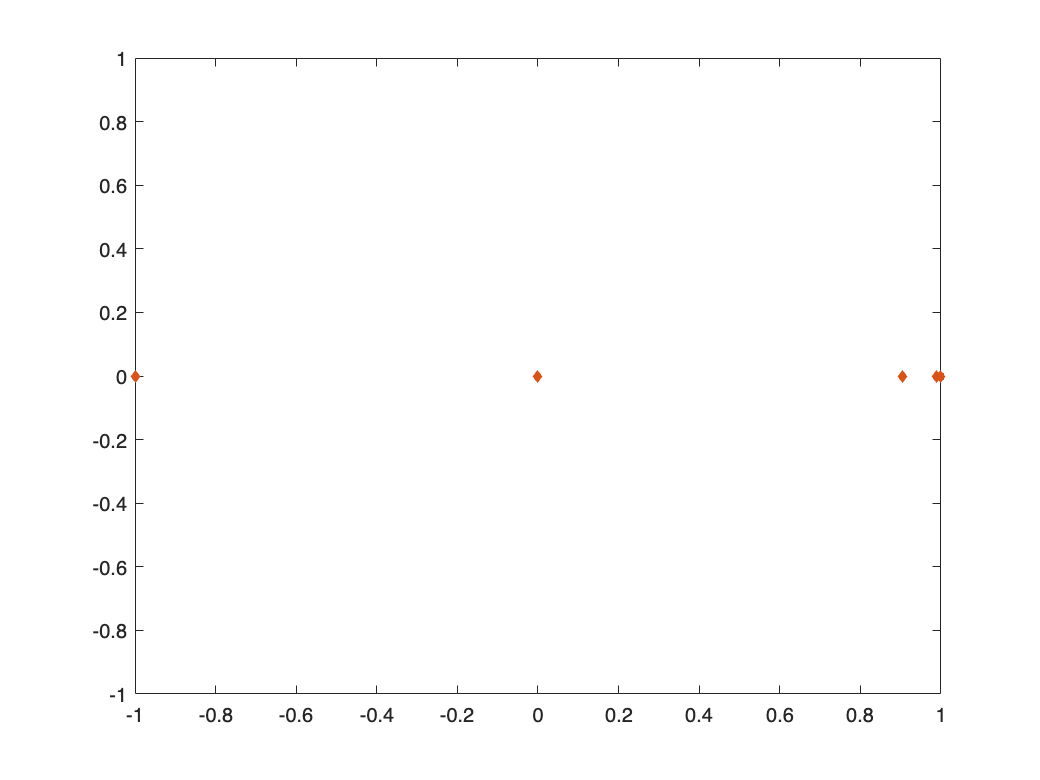


plot(real(autoV(1,1)), imag(autoV(1,1)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,1)), imag(autoV(2,1)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,2)), imag(autoV(1,2)), 'square-.', "MarkerSize", 4 , "MarkerFaceColor", [0.0500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,2)), imag(autoV(2,2)), 'square-.', "MarkerSize", 4 , "MarkerFaceColor", [0.0500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,3)), imag(autoV(1,3)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,3)), imag(autoV(2,3)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,4)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,4)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,5)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,5)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,6)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,6)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

- What could be the behavior of the discrete-time description eigenvalues, when increasing or decreasing the sampling frequency $f_s = 1/ \Delta$ ? 

- Did you find any difference between the free movement of the state of the original continuous-time system and the discrete-time representations you obtained?

- Finally, analysing the results, try to figure out a good choice for $\Omega_{\text{B}}$, or equivalently for $f_{\text{B}}$ , in order to obtain a proficient discrete-time description of the given LTI system.

Now suppose to feed the continuous time system with the input 


$$u(t) = t e^{-4t}\sin \left(2 \pi \bar{f}t - \frac{pi}{6}\right)\cdot 1(t) \quad \bar{f} = 2.0\;\text{[Hz]}$$


and assume to sample also the input signal, beside the state and the output variables.

- Is the previously chosen sampling period still a good choice? Or do you have to select a different value?

- What if $\bar{f} = 200.0 \; \text{[Hz]}$?

- Write a few lines of code, implementing a comparison of the state and output movements, starting from the assigned initial state $x_0$ and the predefined input, for the continuous-time system and the discrete-time representation obtained, discretizing the system equations according to the chosen sampling period.


% write here the code solving the problem 


## Second Scenario: Discretising an LTI System with Complex Eigenvalues

Consider now the continuous-time LTI system


$$\left\{ \begin{array}{lcl}
			\dot{x}(t) &=& \left[ \begin{array}{cc} 
												1 & 2\\-2 & 1 
											\end{array} \right] \cdot x(t) + \left[\begin{array}{c} 0 \\ 10  \end{array} \right] \cdot u(t) \\[0.5em] \\
			y(t) &=&\left[ \begin{array}{cc}
									 1 & 0
									\end{array}  \right] \cdot x(t)
			\end{array} \right.$$


and repeat the same computation steps. What is your finding?


% write here the code solving the problem 


clear
close all
clc
sympref('default');
Ts= 1e-4;
Tc=1e-3;
Ac = [1,2;...
    -2, 1;];
Bc = [0; 10];
Cc = [1,0];
Dc= 0;
sysC = ss( Ac,Bc,Cc, Dc)

sysC =
 
  A = 
       x1  x2
   x1   1   2
   x2  -2   1
 
  B = 
       u1
   x1   0
   x2  10
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


sysD0 = c2d( sysC, Tc )

sysD0 =
 
  A = 
              x1         x2
   x1      1.001   0.002002
   x2  -0.002002      1.001
 
  B = 
              u1
   x1  1.001e-05
   x2       0.01
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.001 seconds
Discrete-time state-space model.


sysD1 = c2d( sysC, Tc*10 )

sysD1 =
 
  A = 
            x1       x2
   x1     1.01   0.0202
   x2  -0.0202     1.01
 
  B = 
             u1
   x1  0.001007
   x2    0.1005
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


sysD2 = c2d( sysC, Tc*100 )

sysD2 =
 
  A = 
            x1       x2
   x1    1.083   0.2196
   x2  -0.2196    1.083
 
  B = 
           u1
   x1  0.1066
   x2   1.045
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


sysD3 = c2d( sysC, Tc*1000 )

sysD3 =
 
  A = 
           x1      x2
   x1  -1.131   2.472
   x2  -2.472  -1.131
 
  B = 
          u1
   x1  13.47
   x2  5.624
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.


sysD4 = c2d( sysC, Tc*10000 )

sysD4 =
 
  A = 
               x1          x2
   x1        8989   2.011e+04
   x2  -2.011e+04        8989
 
  B = 
              u1
   x1       4267
   x2  9.841e+04
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 10 seconds
Discrete-time state-space model.




autoV = [eig(sysC.A) , eig(sysD0.A) , eig(sysD1.A), eig(sysD2.A), eig(sysD3.A), eig(sysD4.A)]

autoV = 1.0e+04 *

   0.0001 + 0.0002i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0001 + 0.0002i   0.8989 + 2.0109i
   0.0001 - 0.0002i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0001 - 0.0000i  -0.0001 - 0.0002i   0.8989 - 2.0109i


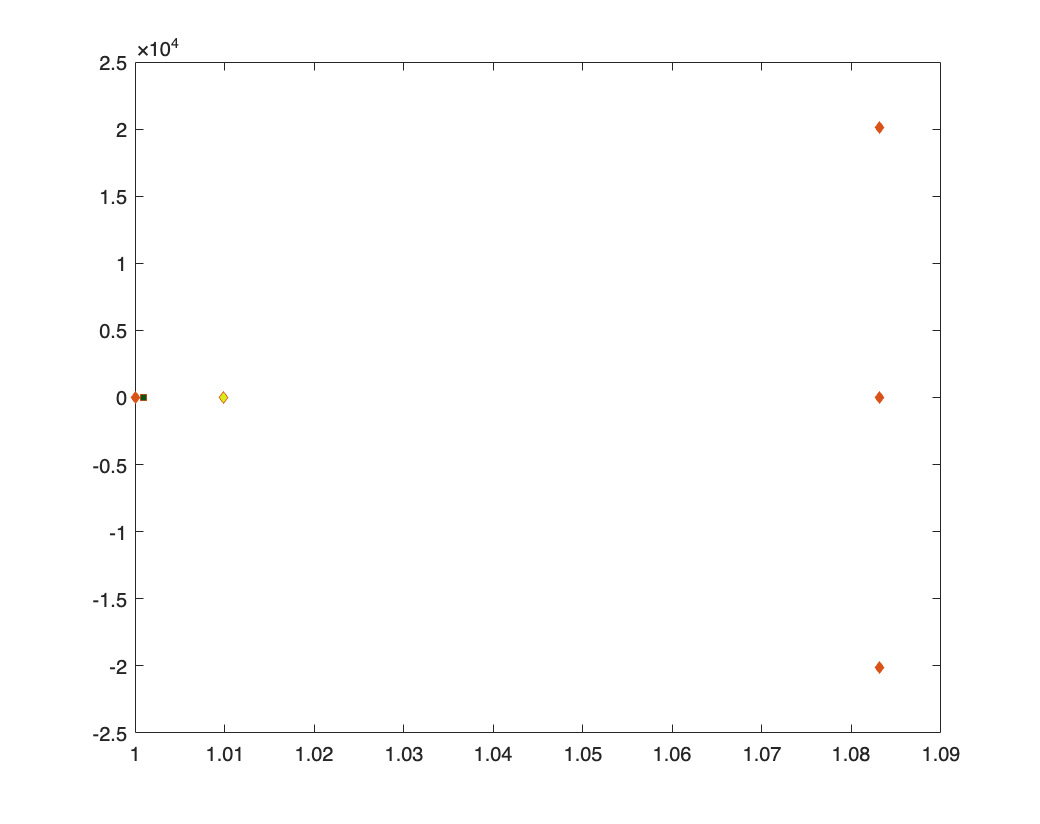


figure('Name','stateSpace','Units','normalized','Position',[10, 10, 75, 95]);

plot(real(autoV(1,1)), imag(autoV(1,1)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,1)), imag(autoV(2,1)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,2)), imag(autoV(1,2)), 'square-.', "MarkerSize", 4 , "MarkerFaceColor", [0.0500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,2)), imag(autoV(2,2)), 'square-.', "MarkerSize", 4 , "MarkerFaceColor", [0.0500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,3)), imag(autoV(1,3)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.9250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,3)), imag(autoV(2,3)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.9250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,4)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,4)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,5)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,5)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

plot(real(autoV(1,4)), imag(autoV(1,6)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;
plot(real(autoV(2,4)), imag(autoV(2,6)), 'diamond-.', "MarkerSize", 4 , "MarkerFaceColor", [0.8500 0.3250 0.0980], "MarkerEdgeColor", [0.8500 0.3250 0.0980]); 
hold on;

Do you find any significant difference by comparing the two cases? 